# Демодуляция ЧМ-сигналов

# Slope Detector

**Для запуска скриптов необходимо корневую папку репозитория сделать рабочей папкой Matlab!**

### 1. Slope Detector

Один самых простых способов демодуляции ЧМ-сигналов заклюключается в преобразовании ЧМ-сигнала в АМ-сигнал. Далее АМ-сигнал можно демодулировать с помощью детектора огибающей. Преобразование сигнала из ЧМ в АМ, можно выполнять, вычисляя от сигнала производную. Схема демодулятора имеет вид:

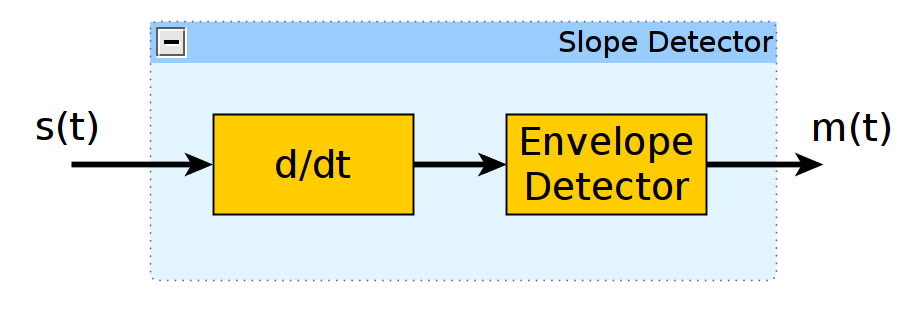

Напомним, что в общем случае частотно-модулированный сигнал можно записать в виде:

 
$$s\left(t\right)=A_с \cdot \cos \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right),$$


где $A_с$ - амплитуда несущей, $f_с$ - частота несущей, $K_f$ - чувствительность модулятора.

Вычислим производную и получим:


$$\frac{d}{\mathrm{dt}}s\left(t\right)=-A_с \cdot \sin \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\cdot \frac{d}{\mathrm{dt}}\left\lbrack 2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right\rbrack =$$



$$=-A_с \cdot \left\lbrack 2\pi f_с +2\pi K_f m\left(t\right)\right\rbrack \cdot \sin \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)\ldotp$$


В результате получили сигнала, который одновременно модулирован и по амплитуде и частоте. Если пропустить этот сигнал, через детектор огибающей, восстановленное сообщение $s_{\mathrm{bb}} \left(t\right)$ (baseband signal) примет вид:


$$s_{\mathrm{bb}} \left(t\right)=A_с \cdot 2\pi f_с +A_с \cdot 2\pi K_f m\left(t\right)\ldotp$$


Если этот сигнала еще подать на усилитель, чтобы сократить на общий множитель, то получим:


$$s_{\mathrm{bb}} \left(t\right)=f_с +K_f m\left(t\right)\ldotp$$


Таким образом, демодулированный сигнал состоит из постоянной составляющей и масштабированного информационного сообщения. Стоит отметить важный момент: чтобы инфромационное сообщение было корректно восстановленно, должно выполняться условие для возможности применения детектора огибающей:


$$f_с +K_f m\left(t\right)>0\ldotp$$


Преобразуем это неравенство, используя минимальное значение сообщение и девиацию:


$$f_с -K_f \cdot \max \left|m\left(t\right)\right|>f_с -\Delta f>0\ldotp$$


То есть, чтобы использовать детектор огибающей, частота несущей должна быть больше девиации.

Рассмотрим, теперь как можно аппартно реализовать приближенное вычисление производной. Известно, что дифференцирование во временной области соответсвует умножению спектра на $j\omega$ в частотной. Значит, для вычисления производной необходимо пропустить сигнала через линейный блок, частотная характеристика которого в полосе сигнала равна $j\omega$. Например, это можно сделать с помощью фильтра верхних частот на основе обычной RC-цепочки. Частотная характериска фильтра равна

$H_{\mathrm{hpf}} =\frac{T\cdot j\omega }{T\cdot j\omega +1}$,

где $T$ - постоянная времени фильтра.

При условии $T\cdot \omega <<1$, частотная характеристика упростится и примет вид:


$$H_{\mathrm{hpf}} =\frac{T\cdot j\omega }{T\cdot j\omega +1}\approx \frac{T\cdot j\omega }{1}\approx T\cdot j\omega \ldotp$$


Это как раз то, что нам и требуется. Условие $T\cdot \omega <<1$ будет выполняться в той полосе частот, где АЧХ фильтра испытывает наклон. Это о дает название демодулятору: slope detector.

Несмотря на то, что устройство демодулятора очень простое, его почти не применяют на практике из-за плохого качества приема при наличии шумов. 

### 2. Демодуляция аудиосообщения

Рассмотрим демодуляцию аудиосообщения с помощью скрипта, реализующего Slope Detector.

В файлах Audio_FM_ModIdx_*.wav записан частотно-модулированный сигнал с различными индексами модуляции. Частота несущей $f_s$ равна 100 kHz, а частота дискретизации $f_s$ = $441$ kHz. Считаем, что прием выполняется квадратурным способ, то есть сигнал имеет вид:


$$s\left(t\right)=A_с \cdot \exp^{j\cdot \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)} \ldotp$$


Дифференцирование будем приближенно вычислять с помощью разности соседних отсчетов. Производная сигнала будет равна:


$$\frac{d}{\mathrm{dt}}s\left(t\right)=j\cdot 2\pi A_с \cdot \left(f_с +K_f \cdot m\left(t\right)\right)\cdot \exp^{j\cdot \left(2\pi f_с t+2\pi K_f \cdot \int_{-\infty }^t m\left(\tau \right)\cdot d\tau \right)} \ldotp$$


Так как полученный сигнал комплексный для вычисления его огибающей достаточно найти его модуль. Тогда сигнал на выходе детектора огибающей при условии $f_с -\Delta f>0$ будет равен:


$$s_{\mathrm{bb}} \left(t\right)=2\pi A_с \cdot \left(f_с +K_f \cdot m\left(t\right)\right)\ldotp$$


После удаления постоянной составляющей и децимации в 10 раз получем восстановленное аудио сообщение.

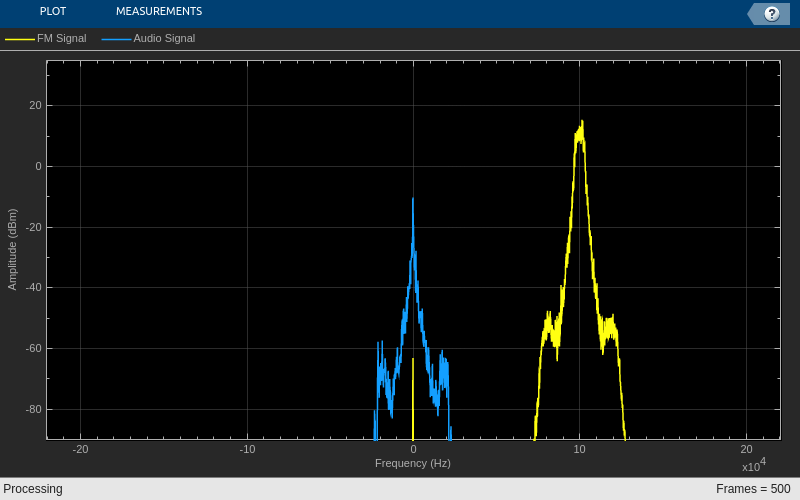

clc; clear; close all;

SignalFrameSize = 10000;          % количество отсчетов чм-сигнала, получаемых за один раз
FramesNumber = 500;               % число обрабатываемых пачек данных
AudioAmp = 1;                     % коэффициент усиления аудиосигнала
RateRatio = 10;                   % коэффициент увеличения частоты дискретизации
ModIndex = '02';    % индекс модуляции

% имя считываемого файла
SignalFileName = sprintf('wav/Audio_FM_ModIdx_%s.wav', ModIndex);

% объект для считываения отсчетов аудиофайла
AudioReader = dsp.AudioFileReader(...
    SignalFileName, ...
    'SamplesPerFrame',SignalFrameSize...
    );

% дополнительные расчеты
SignalFs = AudioReader.SampleRate;              % получаем частоту дискретизации модулированного сигнала
AudioFs = SignalFs / RateRatio;                 % частота дискретизации аудиосообщения

% задержка 
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal', 'Audio Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

Message = [];

% запуск симуляции
for i = 1:FramesNumber
    % считывание отсчетов ЧМ-сигнала
    FmSignal = AudioReader();
    FmSignal = FmSignal(:,1) + 1j*FmSignal(:,2);
 
    % вычисление производной с помощью первой разности
    FmSignalDelayed = DelayBlock(FmSignal);
    DerivativeSignal = FmSignal - FmSignalDelayed;

    % вычисление модуля
    AbsSignal = abs(DerivativeSignal);
    
    % удаляем постоянную составляющую
    AbsSignal = AbsSignal - mean(AbsSignal);
    
    % понижение частоты дискретизации
    Message = [Message; AudioAmp * DownSampler(AbsSignal)];

    % вычисление спектров
    SpectrumData = SpecEstimator([FmSignal AbsSignal]);

    % вывод результатов на график
    Plotter(SpectrumData)

    % задержка в 0.1 секунды для лучшей визуализации
    pause(0.01)
end

На спектрограмме желтым показан спектр частотно-модулированного сигнала, а синим - спектр восстановленного сообщения.

% проигрывание полученного сообщения
sound(Message, AudioFs);

На слух можно оценить, что сообщение восстанавливается без искажений.

### 3. Демодуляция FM-радио в Matlab

Ниже представлен скрипт, позволяющий прослушивать FM-радио с помощью RTL-SDR. Настройка на нужную радиостанцию выполняется с помощью переменной Fc, которая задает частоту несущей. Входной сигнал проходит через фильтр нижных частот для выделения нужной радиостанции. Далее сигнал с помощью умножения на комплексную экспоненту сдвигается на 75 kHz. Это сделано, чтобы выполнялось условие $f_с -\Delta f>0$, так как FM-радиосигнала девиация, как раз, равна 75 kHz. Сдвинутый по частоте сигнал поступает на Slope Detector. В заключение у сигнала удаляется постоянная составляющая, он децимируется и подается на звуковую карту. 

clc; clear; close all;
addpath('matlab/demodulation');

Fc = 106.2e6;                % частота несущей в Hz
SignalFs = 1.2e6;            % частота дискретизации RTL-SDR
AudioFs = 48e3;              % частота дискретизации демодулированного аудиосигнала
SignalFrameSize = 512*25;    % количество отсчетов чм-сигнала, получаемых за один раз
FcShift = 75e3;              % частота сдвига после фильтрации
AudioAmp = 0.2;              % коэффициент усиления аудиосигнала

SDRRTL = comm.SDRRTLReceiver(...
    'RadioAddress', '0',...
    'CenterFrequency', Fc,...
    'EnableTunerAGC', true,...
    'SampleRate', SignalFs, ...
    'SamplesPerFrame', SignalFrameSize,...
    'OutputDataType', 'double' ...
);

% расчет коэффициентов и создание фильтра нижних частот
Fpass = 110e3;
Fstop = 160e3;
H = Audio_Lowpass_FIR_Coeff(SignalFs, Fpass, Fstop);
LowpassFIR = dsp.FIRFilter(H.Numerator);

% генератор для сдвига сигнала по частоте
Mixer = dsp.SineWave(...
    'SampleRate', SignalFs,...
    'SamplesPerFrame', SignalFrameSize,...
    'Frequency', FcShift,...
    'ComplexOutput', true, ...
    'Amplitude', 1);

% задержка на один отсчет
DelayBlock = dsp.Delay;

% дециматор 
DownSampler = dsp.SampleRateConverter(...
    'Bandwidth', 30e3, ...
    'StopbandAttenuation', 80, ...
    'InputSampleRate', SignalFs, ...
    'OutputSampleRate', AudioFs ...
    );

% объект для вычисления спектра
SpecEstimator = dsp.SpectrumEstimator(...
    'PowerUnits','dBm',...
    'FrequencyRange','centered',...
    'SampleRate',SignalFs);

% объект для отрисовки графиков
Plotter = dsp.ArrayPlot(...
    'PlotType','Line', ...
    'XOffset', -SignalFs/2, ...
    'YLimits', [-90, 35], ...
    'XLabel', 'Frequency (Hz)', ...
    'YLabel', 'Amplitude (dBm)', ...
    'ChannelNames', {'FM Signal'}, ...
    'SampleIncrement', SignalFs/SignalFrameSize ...
    );

% воспроизведение аудио сигнала
AudioSink = audioDeviceWriter(AudioFs);

% запуск симуляции
while(true)
    % получение отсчетов сигнала
    FmSignalData = SDRRTL();
    
    % вычисление спектров и вывод результатов на график
    SpectrumData = SpecEstimator(FmSignalData);
    Plotter(SpectrumData);
    
    % удаление постоянной составляющей
    FmSignalData = FmSignalData - mean(FmSignalData);
    
    % фильтрация
    FilteredData = LowpassFIR(FmSignalData);
    
    % сдвиг сигнала по частоте
    MixedData = FilteredData .* Mixer();
    
    % вычисление производной с помощью первой разности
    MixedDataDelayed = DelayBlock(MixedData);
    DerivativeSignal = MixedData - MixedDataDelayed;
    
    % вычисление модуля
    AbsSignal = abs(DerivativeSignal);
    
    % удаляем постоянную составляющую
    AbsSignal = AbsSignal - mean(AbsSignal);
    
    % уменьшение частоты дискретизации
    AudioData = DownSampler(AbsSignal);
   
    % проигрывание данных
    AudioSink(AudioData * AudioAmp);
  
end

### 4. Демодуляция FM-радио в Simulink

В файле FM_SDR_Receiver_Slope_Detector.slx представлена Simulink-модель, позволяющая прослушивать FM-радио с помощью RTL-SDR. Все преобразования сигнала совпадают с теми, что ранее были описаны в Matlab скрипте.

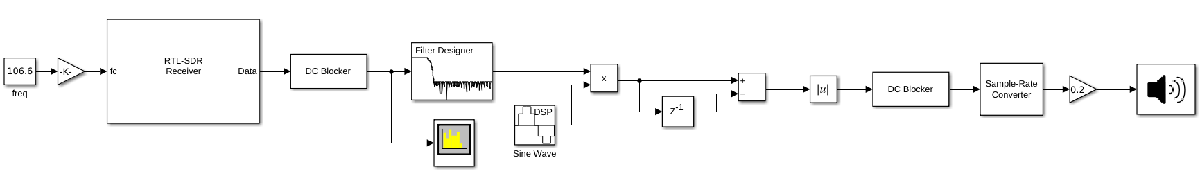

### Литература:

- B. P. Lathi Modern Digital and Analog Communication Systems

- R. Stewart, K. Barlee, D. Atkinson, L. Crockett Software Defined Radio using MATLAB® & Simulink and the RTL-SDR